# BP 神经网络数据预测

- [Zhihu: https://www.zhihu.com/people/1105936347](https://www.zhihu.com/people/1105936347)

- [Github: https://github.com/AFei19911012](https://github.com/AFei19911012)

**此案例可以帮助理解 BP 神经网络的实现机制**

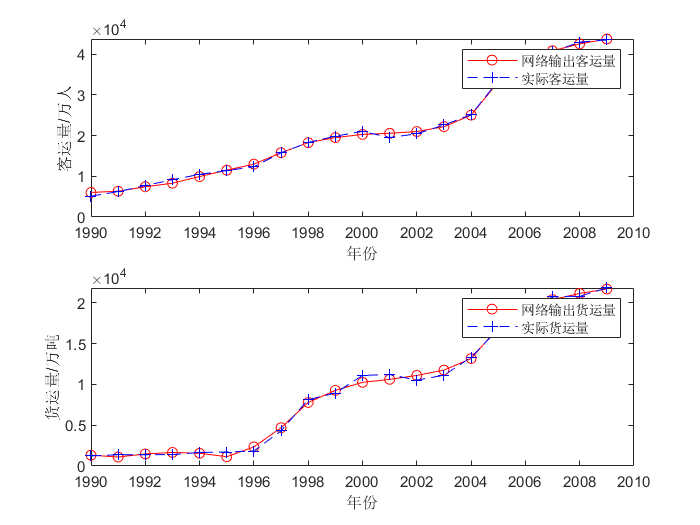

clear; clc;
% 原始数据 
% 人数(单位：万人)
sqrs = [20.55 22.44 25.37 27.13 29.45 30.10 30.96 34.06 36.42 38.09 39.13 39.99 ...
       41.93 44.59 47.30 52.89 55.73 56.76 59.17 60.63];
% 机动车数(单位：万辆)
sqjdcs = [0.6 0.75 0.85 0.9 1.05 1.35 1.45 1.6 1.7 1.85 2.15 2.2 2.25 2.35 2.5 2.6...
        2.7 2.85 2.95 3.1];
% 公路面积(单位：万平方公里)
sqglmj = [0.09 0.11 0.11 0.14 0.20 0.23 0.23 0.32 0.32 0.34 0.36 0.36 0.38 0.49 ... 
         0.56 0.59 0.59 0.67 0.69 0.79];
% 公路客运量(单位：万人)
glkyl = [5126 6217 7730 9145 10460 11387 12353 15750 18304 19836 21024 19490 20433 ...
        22598 25107 33442 36836 40548 42927 43462];
% 公路货运量(单位：万吨)
glhyl = [1237 1379 1385 1399 1663 1714 1834 4322 8132 8936 11099 11203 10524 11115 ...
        13320 16762 18673 20724 20803 21804];
%%%%%%% 网络设置
train_num = 20;       % 学习样本数量
forcast_num = 2;      % 预测样本数量
hidden_unit_num = 8;  % 隐含层
in_dim = 3;           % 输入层
out_dim = 2;          % 输出层
p = [sqrs; sqjdcs; sqglmj];  % 输入数据矩阵
t = [glkyl; glhyl];          % 目标数据矩阵
% 归一化
[SamIn, PSp] = mapminmax(p, -1, 1);
[tn, PSt] = mapminmax(t, -1, 1);
SamOut = tn;         % 输出样本
MaxEpochs = 50000;   % 最大训练次数
lr = 0.05;           % 学习率
E0 = 1e-3;           % 目标误差
rng('default');
% 初始化权值、阈值
W1 = rand(hidden_unit_num, in_dim);    % 初始化输入层与隐含层之间的权值
B1 = rand(hidden_unit_num, 1);         % 初始化输入层与隐含层之间的阈值
W2 = rand(out_dim, hidden_unit_num);   % 初始化输出层与隐含层之间的权值              
B2 = rand(out_dim, 1);                 % 初始化输出层与隐含层之间的阈值
ErrHistory = zeros(MaxEpochs, 1); 
%%%%%%% 训练
for i = 1 : MaxEpochs   
    HiddenOut = logsig(W1*SamIn + repmat(B1, 1, train_num));   % 隐含层网络输出
    NetworkOut = W2*HiddenOut + repmat(B2, 1, train_num);      % 输出层网络输出
    Error = SamOut - NetworkOut;       % 实际输出与网络输出之差
    SSE = sumsqr(Error);               % 能量函数（误差平方和）
    ErrHistory(i) = SSE;
    if SSE < E0
        break;
    end
    % 以下六行是 BP 网络最核心的程序
    % 权值（阈值）依据能量函数负梯度下降原理所作的每一步动态调整量
    Delta2 = Error;
    Delta1 = W2' * Delta2 .* HiddenOut .* (1 - HiddenOut);    
    dW2 = Delta2 * HiddenOut';
    dB2 = Delta2 * ones(train_num, 1); 
    dW1 = Delta1 * SamIn';
    dB1 = Delta1 * ones(train_num, 1);
    % 对输出层与隐含层之间的权值和阈值进行修正
    W2 = W2 + lr * dW2;
    B2 = B2 + lr * dB2;
    % 对输入层与隐含层之间的权值和阈值进行修正
    W1 = W1 + lr * dW1;
    B1 = B1 + lr * dB1;
end
% 隐含层输出最终结果
HiddenOut = logsig(W1*SamIn + repmat(B1, 1, train_num));
% 输出层输出最终结果
NetworkOut = W2*HiddenOut + repmat(B2, 1, train_num);
% 反归一化
a = mapminmax('reverse', NetworkOut, PSt);
x = 1990 : 2009;      % 时间轴刻度
newk = a(1, :);       % 网络输出客运量
newh = a(2, :);       % 网络输出货运量
subplot(2, 1, 1);
plot(x, newk, 'r-o', x, glkyl, 'b--+');
legend('网络输出客运量', '实际客运量');
xlabel('年份');
ylabel('客运量/万人');
subplot(2, 1, 2);
plot(x, newh, 'r-o', x, glhyl, 'b--+');
legend('网络输出货运量', '实际货运量');
xlabel('年份');
ylabel('货运量/万吨');

% 利用训练好的网络进行预测
% 2010年和2011年的相关数据
pnew=[73.39 75.55
      3.9635 4.0975
      0.9880 1.0268];  
pnewn = mapminmax('apply', pnew, PSp);
% 隐含层输出预测结果
HiddenOut = logsig(W1*pnewn + repmat(B1, 1, forcast_num));
% 输出层输出预测结果
anewn = W2*HiddenOut + repmat(B2, 1, forcast_num);
anew = mapminmax('reverse', anewn, PSt); 
disp('预测值d：');

预测值d：


disp(anew);

   1.0e+04 *
    4.4038    4.4023
    2.1837    2.1831
